load('20181125.mat')
[mdl, FitInfo5] = fitrlinear(TrainData, Quality)

mdl =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [11×1 double]
                 Bias: 6.0000
               Lambda: 2.0416e-04
              Learner: 'svm'


  Properties, Methods


FitInfo5 = 다음 필드를 포함한 struct :
                    Lambda: 2.0416e-04
                 Objective: 0.5828
            IterationLimit: 1000
             NumIterations: 2
              GradientNorm: 22.2282
         GradientTolerance: 1.0000e-06
      RelativeChangeInBeta: 6.8873e-05
             BetaTolerance: 1.0000e-04
             DeltaGradient: []
    DeltaGradientTolerance: []
           TerminationCode: 1
         TerminationStatus: {'계수에 대한 허용오차가 충족되었습니다.'}
                   History: []
                   FitTime: 0.0020
                    Solver: {'bfgs'}


lambda1 = logspace(-5, -1, 15)

lambda1 =     0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0010    0.0019    0.0037    0.0072    0.0139    0.0268    0.0518    0.1000


CVMdl2 = fitrlinear(TrainData', Quality, 'ObservationsIn','columns','KFold',5,'Lambda',lambda,'Learner','leastsquares','Solver','sparsa','Regularization','lasso')

CVMdl2 =   classreg.learning.partition.RegressionPartitionedLinear
    CrossValidatedModel: 'Linear'
           ResponseName: 'Y'
        NumObservations: 4898
                  KFold: 5
              Partition: [1×1 cvpartition]
      ResponseTransform: 'none'


  Properties, Methods



ge2 = kfoldLoss(CVMdl2)

ge2 = 0.7827

x = TrainData;
y = Quality;
a = 1;
b = 1;


%설명
%lamda값을 어디에 쓰려고 했었는데 기억이 안남...

[H, FitInfo4] = lasso(TrainData, Quality, 'Alpha', 0.3, 'CV', 10);
idxH1SE = FitInfo4.Index1SE;
idxHMINSE = FitInfo4.IndexMinMSE;

Hcoef = H(:,idxH1SE);
Hcoef0 = FitInfo4.Intercept(idxHMINSE);
lamdaH = FitInfo4.LambdaMinMSE;
HResult = TrainData*Hcoef + Hcoef0;

[J, FitInfo6] = lasso(TrainData, Quality, 'Alpha',0.5, 'CV',10);
[K, FitInfo7] = lasso(TrainData, Quality, 'Alpha', 0.3, 'CV',15);

idxJ1SE = FitInfo6.Index1SE;
idxK1SE = FitInfo7.Index1SE;

idxJMinMSE = FitInfo6.IndexMinMSE;
idxKMinMSE = FitInfo7.IndexMinMSE;

Jcoef = J(:,idxJ1SE);
Jcoef0 = FitInfo6.Intercept(idxJMinMSE);

Kcoef = K(:, idxK1SE);
Kcoef0 = FitInfo7.Intercept(idxKMinMSE);

JResult = TrainData*Jcoef + Jcoef0;
KResult = TrainData*Kcoef + Kcoef0;

yhatH = mean(HResult)

yhatH = 118.1815

yHatJ = mean(JResult)

yHatJ = 120.5985

yHatK = mean(KResult)

yHatK = 118.2672


weightsH = @(yhatH) 1./((a+b * abs(yhatH)).^2);
weightsJ = @(yhatJ) 1./((a+b * abs(yhatJ)).^2);
weightsK = @(yhatK) 1./((a+b * abs(yhatK)).^2);

%mdl1 = CVMdl2.Trained{1}

%beta0 : 각 성분이랑 Quality 사이의 상관관계
beta0 = [FixAcidCorr(1,2); VolAcidCorr(1,2); CitAcidCorr(1,2); ResSugarCorr(1,2); ChloridesCorr(1,2); FreeS02Corr(1,2); TotalS02Corr(1,2); DensityCorr(1,2); pHCorr(1,2); SulphatesCorr(1,2); AlcoholCorr(1,2)]

beta0 =    -0.1137
   -0.1947
   -0.0092
   -0.0976
   -0.2099
    0.0082
   -0.1747
   -0.3071
    0.0994
    0.0537


mdl2 = fitnlm(x,y,@hougen, beta0, 'Weights', weightsH);

mdl3 = fitnlm(x,y,@hougen, beta0, 'Weights', weightsJ);

mdl4 = fitnlm(x,y,@hougen, beta0, 'Weights', weightsK);


rmseMdl2 = mdl2.RMSE

rmseMdl2 = 0.5276

mseMdl2 = mdl2.MSE

mseMdl2 = 0.2784


rmaseMdl3 = mdl3.RMSE

rmaseMdl3 = 0.5276

mseMdl3 = mdl3.MSE

mseMdl3 = 0.2784


rmaseMdl4 = mdl4.RMSE

rmaseMdl4 = 0.5276

mseMdl4 = mdl4.MSE

mseMdl4 = 0.2784

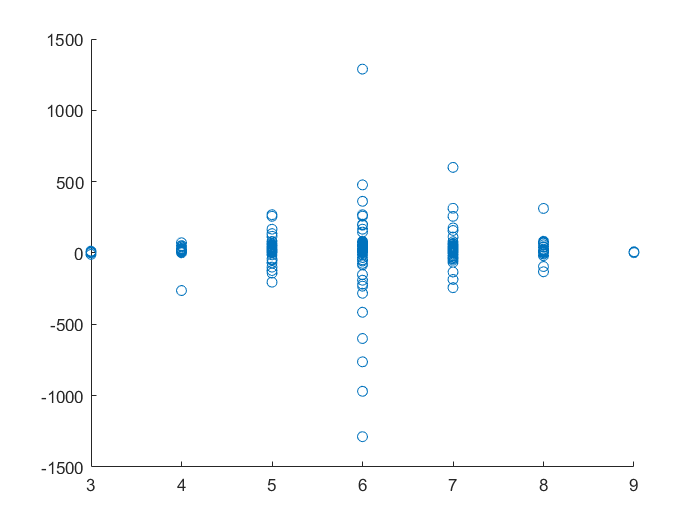


%이게 경고가 떠서 그런건지 모르겠는데 다르게 돌린 FitInfo가 mean(result)값도 다른데 왜 rmas, mse는 똑같이 나오는지 아직 모르겠음

resH = predict(mdl2, TrainData);
resJ = predict(mdl3, TrainData);
resK = predict(mdl4, TrainData);

figure
scatter(Quality, resH)


figure
scatter(Quality, resJ)


figure
scatter(Quality, resK)